%LOAD DATA 

foldernam = "Evolution - Praful\"

foldernam = "Evolution - Praful\"

filnam = foldernam +  "1_CCRN_1_cat"

filnam = "Evolution - Praful\1_CCRN_1_cat"

model_nam = "1-CCRN-1-cat"

model_nam = "1-CCRN-1-cat"


load(foldernam + 'Data\' + model_nam + '_Ham.mat')
load(foldernam + 'Data\' + model_nam + '_hcnet.mat')

hc_net

hc_net =      1     3     2


%----straight line initial condition

%number of points in the trajectory
traj_pts = 500;

%List of roots
pos_root_arr = double(pos_root_arr)

pos_root_arr =     0.7999    0.3106    0.1206
    0.2001    0.0194    0.0019
    1.9000    1.7525    1.6164



%start & end point
start_idx = 2; end_idx = 1;

%get straight line initial condition joining the end points
q_IC = straight_line_IC(traj_pts,pos_root_arr,start_idx,end_idx);


%For descent 
traj = q_IC;


%Initialize Descender by getting a phase space (PS) trajectory from x_ic
Initialize_descender

S_arr = 0.2308

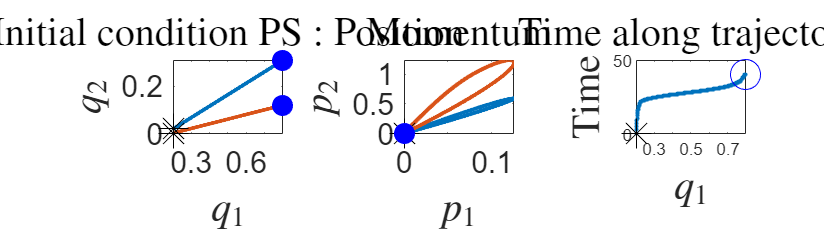

%Plot initial Phase space trajectory
plotnam = "Initial condition PS";
save_plot_name = foldernam + 'Plots\'+model_nam+'_IC_PS_traj.png';
save_plot_flag = 0; %change to 1 to save
plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,save_plot_flag)

%Create a .mat file for saving data
savenam = foldernam + 'Data\' + model_nam + '_descend_'+string(start_idx)...
    +'_'+string(end_idx)+'_straightIC_'+string(traj_pts)+'_'+string(date)+'.mat'

savenam = "Evolution - Praful\Data\1-CCRN-1-cat_descend_2_1_straightIC_500_06-Dec-2023.mat"

## Actual descent

%Actual descender parameters

%step size
eps_ic = 1; eps = eps_ic; eps_min = 0.01;    

%Action threshold settings
delta_S = 10; err_thresh = 10^(-1); 
eps_S_thresh = 10^(-7); delta_S_thresh = 10^(-7);
delta_S_thresh_eps = 10^(-7);

%low pass filter settings
f0 = 2; f0_max = 40; f0_step = 0.1; 
time_uniform_f = 45;

%Distance to Hamilton's EoM settings
 a_min=100; a_thresh = 0.001;

%iteration settins
iter_max = 20; iter = 1;

format long

while f0<f0_max  &&  iter<iter_max && a_min>a_thresh
    iter = iter + 1
    traj_pts = size(traj,1);

    %take a step in the gradient by picking appropriate step size
    [eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
        (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,delta_x_s,action_S,eps,num_smooth,eps_min,delta_S_thresh_eps);
    traj = PS_traj(:,1:num_spec);
    delta_S = action_S_new - action_S;
    [iter, eps, action_S_new, delta_S, f0]
    eps_used = eps;

    
    f0

    if abs(delta_S)<delta_S_thresh || eps < eps_min
        f0 = f0 + 0.1; eps = eps_ic; delta_S = 1;  
        traj = time_uniform_filter(traj,t_traj,traj_pts,time_uniform_f);
        [traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);
        [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
    end

    
    %smoothen gradient for next iteration
    delta_x_s =  smooth_traj_butter(delta_x,f0); 

    %Find closest distance by integrating HamEoM
    a_min = ham_closest_approach_noplot(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam)

    
    %Update descender and save to file
    Update_descender
    save(savenam)
    
    %Plot some stuff in every some iterations
    %{
    if mod(iter,10)==0
        save_plot_name_root = foldernam + 'Plots\'+model_nam;
        save_plot_name = save_plot_name_root +'_deltax_'+string(iter)+'.png'
        debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,1);
        save_plot_name = save_plot_name_root +'_PS_traj_'+string(iter)+'.png'
        plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,1);
        save_plot_name = save_plot_name_root + '_HamEoM_' + string(iter)+'.png';
        a = ham_closest_approach(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam)
    end
    %}
    
end

iter =      2


delta_S =    6.574982175344433


delta_S =    1.313247618228472


delta_S =    0.472222659968223


delta_S =    0.224571798543781


delta_S =    0.045061917061406


delta_S =   -0.028022513969239


ans =    2.000000000000000   0.031250000000000   0.202734367134895  -0.028022513969239   2.000000000000000


f0 =      2


a_min =    0.480192073386016


iter =      3


delta_S =    0.115026032829492


delta_S =   -0.013352190637425


ans =    3.000000000000000   0.015625000000000   0.189382176497470  -0.013352190637425   2.000000000000000


f0 =      2


a_min =    0.480616914545933


iter =      4


delta_S =   -0.062320601610660


ans =    4.000000000000000   0.015625000000000   0.127061574886810  -0.062320601610660   2.000000000000000


f0 =      2


a_min =    0.485991823549625


iter =      5


delta_S =   -0.009923083015361


ans =    5.000000000000000   0.015625000000000   0.117138491871449  -0.009923083015361   2.000000000000000


f0 =      2


a_min =    0.488603315056626


iter =      6


delta_S =   -0.006963320968623


ans =    6.000000000000000   0.015625000000000   0.110175170902825  -0.006963320968623   2.000000000000000


f0 =      2


a_min =    0.489974172980641


iter =      7


delta_S =   -0.004257126960430


ans =    7.000000000000000   0.015625000000000   0.105918043942395  -0.004257126960430   2.000000000000000


f0 =      2


a_min =    0.491362768845679


iter =      8


delta_S =   -0.003031460283577


ans =    8.000000000000000   0.015625000000000   0.102886583658818  -0.003031460283577   2.000000000000000


f0 =      2


a_min =    0.495157853639886


iter =      9


delta_S =   -0.001841938969336


ans =    9.000000000000000   0.015625000000000   0.101044644689482  -0.001841938969336   2.000000000000000


f0 =      2


a_min =    0.496215327753490


iter =     10


delta_S =   -0.001436725763371


ans =   10.000000000000000   0.015625000000000   0.099607918926111  -0.001436725763371   2.000000000000000


f0 =      2


a_min =    0.494832579203160


iter =     11


delta_S =     -9.239190072756059e-04


ans =   11.000000000000000   0.015625000000000   0.098683999918835  -0.000923919007276   2.000000000000000


f0 =      2


a_min =    0.494315587953233


iter =     12


delta_S =     -7.958459257348394e-04


ans =   12.000000000000000   0.015625000000000   0.097888153993101  -0.000795845925735   2.000000000000000


f0 =      2


a_min =    0.497233492475380


iter =     13


delta_S =     -4.706328041196028e-04


ans =   13.000000000000000   0.015625000000000   0.097417521188981  -0.000470632804120   2.000000000000000


f0 =      2


a_min =    0.494576999814319


iter =     14


delta_S =     -4.555736960887152e-04


ans =   14.000000000000000   0.015625000000000   0.096961947492892  -0.000455573696089   2.000000000000000


f0 =      2


a_min =    0.495817226253883


iter =     15


delta_S =     -2.508752800001873e-04


ans =   15.000000000000000   0.015625000000000   0.096711072212892  -0.000250875280000   2.000000000000000


f0 =      2


a_min =    0.494797744032388


iter =     16


delta_S =     -2.674379834209373e-04


ans =   16.000000000000000   0.015625000000000   0.096443634229471  -0.000267437983421   2.000000000000000


f0 =      2


a_min =    0.494993947935200


iter =     17


delta_S =     -1.310600211422430e-04


ans =   17.000000000000000   0.015625000000000   0.096312574208329  -0.000131060021142   2.000000000000000


f0 =      2


a_min =    0.494522334560409


iter =     18


delta_S =     -1.605945657243979e-04


ans =   18.000000000000000   0.015625000000000   0.096151979642604  -0.000160594565724   2.000000000000000


f0 =      2


a_min =    0.494253782767292


iter =     19


delta_S =     -6.706237079495692e-05


ans =   19.000000000000000   0.015625000000000   0.096084917271810  -0.000067062370795   2.000000000000000


f0 =      2


a_min =    0.493967047631996


iter =     20


delta_S =     -9.892645431282265e-05


ans =   20.000000000000000   0.015625000000000   0.095985990817497  -0.000098926454313   2.000000000000000


f0 =      2


a_min =    0.493476096622997


format short

f0_arr

f0_arr =      3
     2
     2
     2
     2
     2
     2
     2
     2
     2


format long
S_arr(end)

ans =    0.095985990817497


format long
S_arr(end)

ans =    0.095985990817497


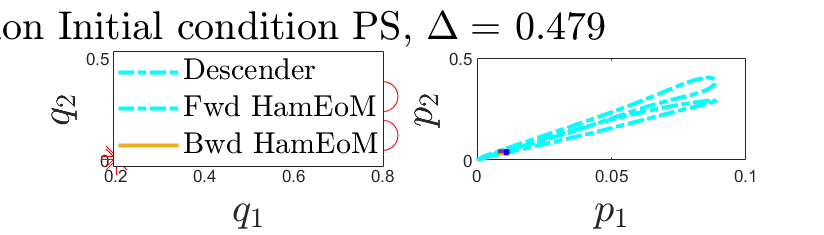

a_min =    0.478683476937924


    a_min = ham_closest_approach(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam)

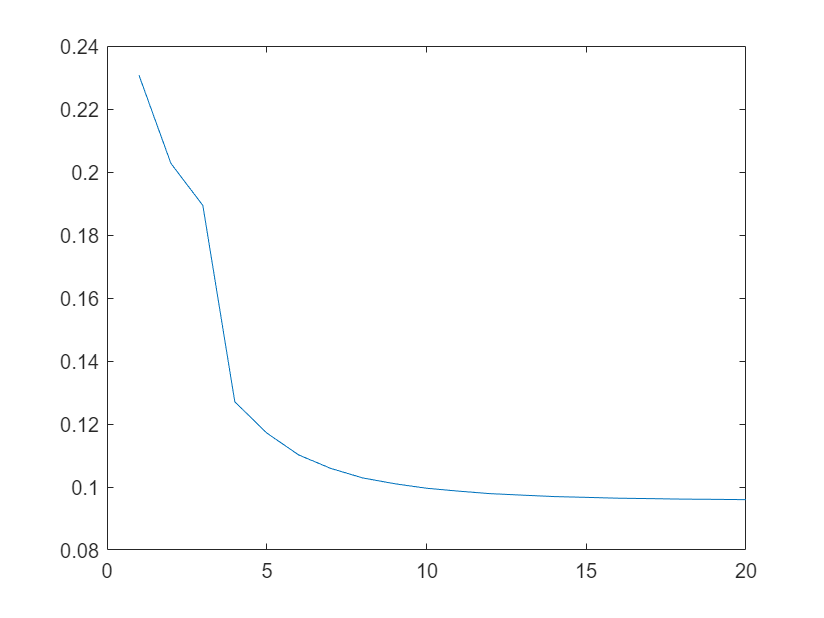

figure()
plot(S_arr)

figure()
plot(S_arr)

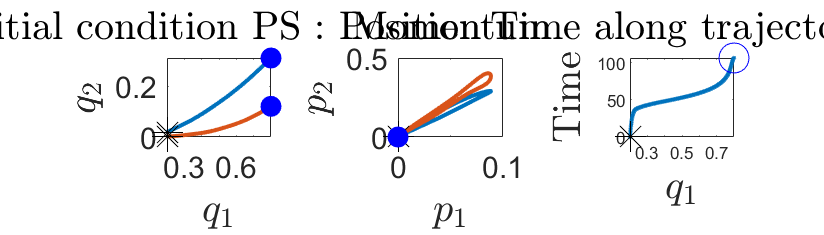

plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,1);

%size(conc_traj)

format long
anneal_ct = 0;
while f0<f0_max  &&  iter<iter_max
    iter = iter + 1;
    traj_pts = size(traj,1);


    %take a step in the gradient by picking appropriate step size
    [eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
        (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,...
        delta_x_s,action_S,eps,num_smooth,eps_min,delta_S_thresh);
    traj = PS_traj(:,1:num_spec);
    delta_S = action_S_new - action_S;
    [iter, eps, action_S_new, delta_S, f0]
    eps_used = eps;
    %if delta_S is positive, then break. If less than threshold then
    %increase cutoff frequency. If descent has stopped, anneal.
    %{
    if delta_S > 0
        disp('Why is action increasing? Error!')
        break
    
    elseif eps == 0
        anneal_ct = anneal_ct + 1;
        f0 = f0 - 0.1; eps = 0.5; delta_S = 1; traj_pts_new = traj_pts;
        if anneal_ct >2
            disp('Annealing')
            traj_pts_new = traj_pts+1000;
            f0 = f0; eps = 1; delta_S = 1;  traj_pts = traj_pts_new;
            anneal_ct = 0;
        end
        traj = time_uniform_filter(traj,t_traj,traj_pts_new,35);
        [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
        %}
    if f0 > 6
        f0 = f0; eps = 0.5; delta_S = 1; traj_pts_new = traj_pts;
        traj_pts_new = traj_pts+1000;
        traj = time_uniform_filter(traj,t_traj,traj_pts_new,35);
        [traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);
        [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    

    elseif abs(delta_S)<delta_S_thresh || eps < eps_min
        f0 = f0 + 0.1; eps = 1; delta_S = 1;  
        traj = time_uniform_filter(traj,t_traj,traj_pts,35);
        [traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);
        [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
    end

    
    %smoothen gradient for next iteration
    delta_x_s =  smooth_traj_butter(delta_x,f0); 

    
    %Update descender and save to file
    Update_descender
    save(savenam)
    
    %Plot some stuff in every some iterations
    if mod(iter,5)==0
        save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
        +'_'+string(stab_pt_choice)+'_deltax_'+string(iter)+'.png'
        plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,0);
        debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);
    end

    
end

